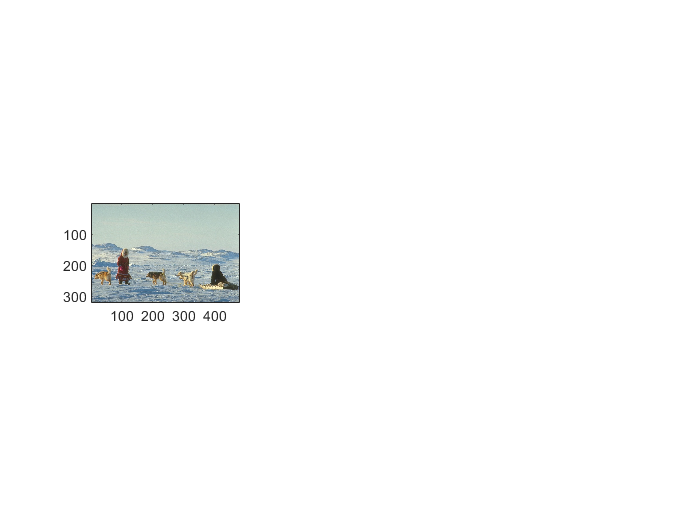

img = imread('./images/310007.jpg');
subplot(1,3,1); imagesc(img); axis image;

[X,L] = getfeatures(img, 7);
XX = [X(1:2,:); X(3:4,:)/10];

K=10;
% Y = kmeans(XX, K, 0.5);
Y = kmeans_plus(XX, K, 0.8, 0.6, 0.4);

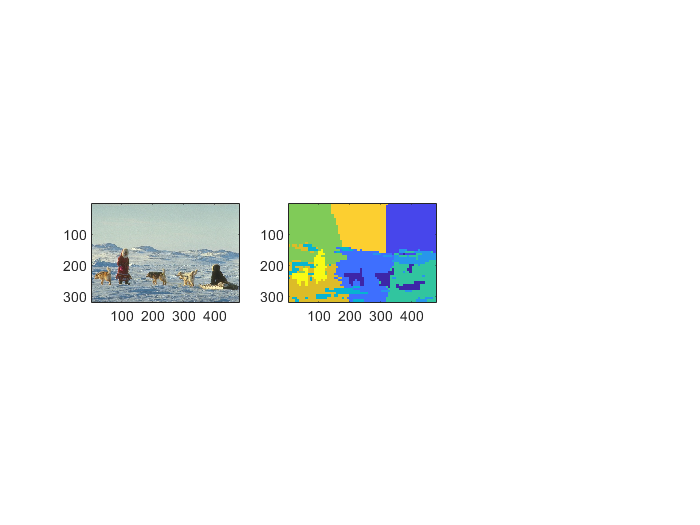

segm = labels2segm(Y,L);
subplot(1,3,2); imagesc(segm); axis image;

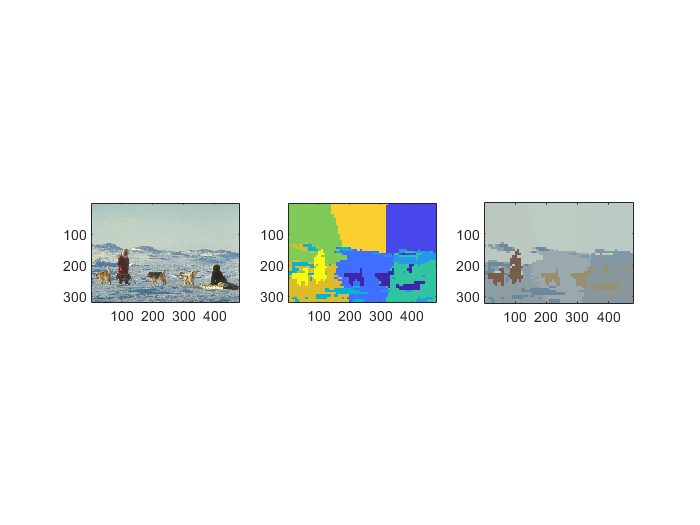

csegm = colorsegm(segm,img);
subplot(1,3,3); imagesc(csegm); axis image;

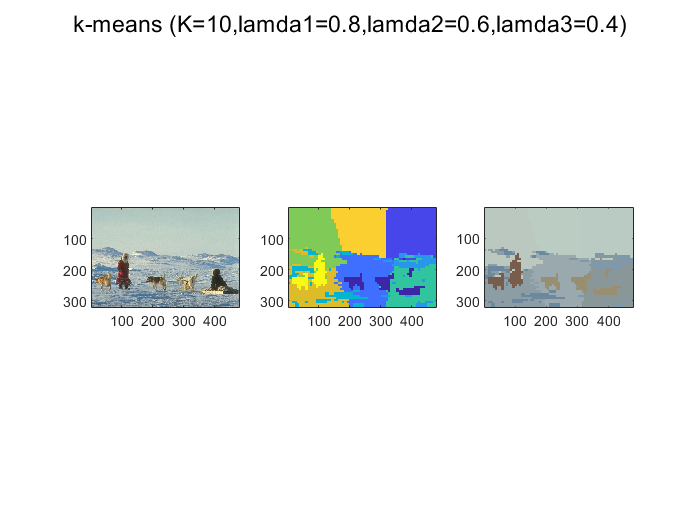

sgtitle('k-means (K=10,lamda1=0.8,lamda2=0.6,lamda3=0.4)');